% TASK 4
% Start of script. clear any remaining variables from previous script runs.
clear

% Number of samples used for testing (number of elements of the data vector).
N =5000

N = 5000

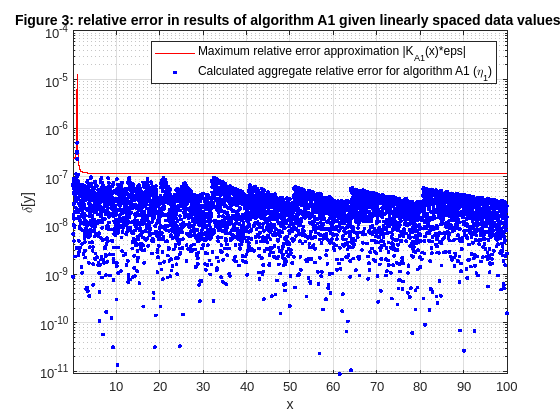

% initializing vectors of data:
% x:  vector of linearly spaced data values.
% xl: vector of logarithmically spaced data values.
x = linspace(10^-2, 10^2, N);
xl = logspace(-2, 2, N);

% Defining function f(x) originally given in the assignement A description,
% as well as the coefficients describing the propogation of rounding errors
% in algorithm A1 (KA1) and in algorithm A2 (KA2). Both of these
% coefficients were derived in Task 3.
f = @(x) (atan(x)./x.^2) - x.^3;
KA1 = @(x) 3*abs(1+x.^3./f(x))+abs(x.^3./f(x))+1;
KA2 = @(x) 3+abs(x.^3./f(x))+abs(atan(x)./(x.^2.*f(x)));

% Calculating the vector of non-error-corrupted values of the
% results of f(x) (here named y). It is here done for linearly
% spaced values of the data.
y = f(x);

% The same operation as the last step, but here done for the vector
% of logarithmically spaced data values xl.
yl = f(xl);

% The steps of the algorith A1 performed one by one. The conversion to the
% 'single' representation is here used to round the values and introduce
% the rounding error. The rounding is done after each step. After rounding
% we convert back to double representation to allow for further operations.
% Here the algorithm is applied to linearly spaced values of the data. The result is
% stored in y_err1.
v1_1 = double(single(   atan(x)  ));
v2_1 = double(single(     x.^2   ));
v3_1 = double(single( v1_1./v2_1 ));
v4_1 = double(single(    x.^3    ));
v5_1 = double(single( v3_1-v4_1  ));
y_err1 = v5_1;

% The steps of the algorith A2 performed one by one. Here the algorithm 
% is applied to linearly spaced values of the data. The result is
% stored in y_err2.
v1_2 = double(single(   atan(x)  ));
v2_2 = double(single(    x.^5    ));
v3_2 = double(single(  v1_2-v2_2 ));
v4_2 = double(single(    x.^2    ));
v5_2 = double(single( v3_2./v4_2 ));
y_err2 = v5_2;

% The steps of the algorith A1 performed one by one. Here the algorithm 
% is applied to logarithmically spaced values of the data. The result is
% stored in yl_err1.
vl1_1 = double(single(   atan(xl)   ));
vl2_1 = double(single(     xl.^2    ));
vl3_1 = double(single( vl1_1./vl2_1 ));
vl4_1 = double(single(    xl.^3     ));
vl5_1 = double(single( vl3_1-vl4_1  ));
yl_err1 = vl5_1;

% The steps of the algorith A2 performed one by one. Here the algorithm 
% is applied to logarithmically spaced values of the data. The result is
% stored in yl_err2.
vl1_2 = double(single(   atan(xl)   ));
vl2_2 = double(single(    xl.^5     ));
vl3_2 = double(single(  vl1_2-vl2_2 ));
vl4_2 = double(single(    xl.^2     ));
vl5_2 = double(single( vl3_2./vl4_2 ));
yl_err2 = vl5_2;

% Calulating the relative error in the result using the definition for
% relative error. dy1 is the error in y1_err1, dyl1 is the error in yl_err1,
% dy2 is the error in y_err2, dyl2 is the error in yl_err2. The
% reason for taking the absolute value of the error is because we are
% interested only in the error magnitude.
dy1 = abs((y_err1-y)./y);
dy2 = abs((y_err2-y)./y);
dyl1 = abs((yl_err1-yl)./yl);
dyl2 = abs((yl_err2-yl)./yl);

% Calculating the maximum relative error due to rounding.
epssin = eps("single")/2;

% Code for the generation of figure 3.
figure(3);
plot(x,KA1(x)*epssin,"r-")
hold on;grid on;
axis([0.01,100,-inf,1e-4])
plot(x,dy1,"b.");
xlabel('x');
ylabel('\delta[y]');
legend("Maximum relative error approximation |K_{A1}(x)*eps|","Calculated aggregate relative error for algorithm A1 (\eta_{1})")
title("Figure 3: relative error in results of algorithm A1 given linearly spaced data values.")
yscale log;hold off;

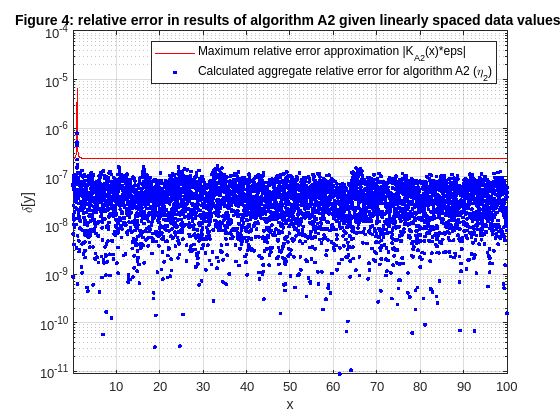


% Code for the generation of figure 4.
figure(4);
plot(x,KA2(x)*epssin,"r-")
hold on;grid on;
axis([0.01,100,-inf,1e-4])
plot(x,dy2,"b.");
xlabel('x');
ylabel('\delta[y]');
legend("Maximum relative error approximation |K_{A2}(x)*eps|","Calculated aggregate relative error for algorithm A2 (\eta_{2})")
title("Figure 4: relative error in results of algorithm A2 given linearly spaced data values.")
yscale log;hold off;

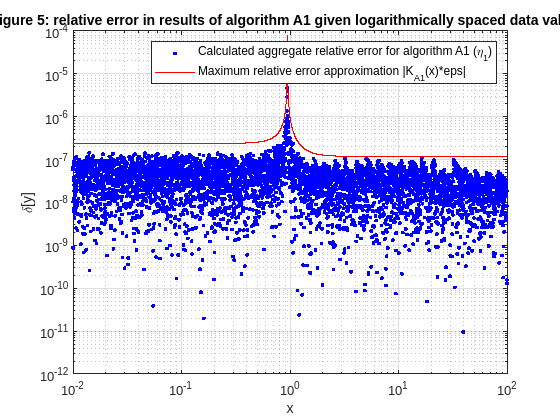


% Code for the generation of figure 5.
figure(5);
loglog(xl, dyl1, 'b.');
hold on;grid on;
loglog(xl,KA1(xl)*epssin,"r-")
xlabel('x');
ylabel('\delta[y]');
legend("Calculated aggregate relative error for algorithm A1 (\eta_{1})","Maximum relative error approximation |K_{A1}(x)*eps|")
title("Figure 5: relative error in results of algorithm A1 given logarithmically spaced data values.")
hold off;

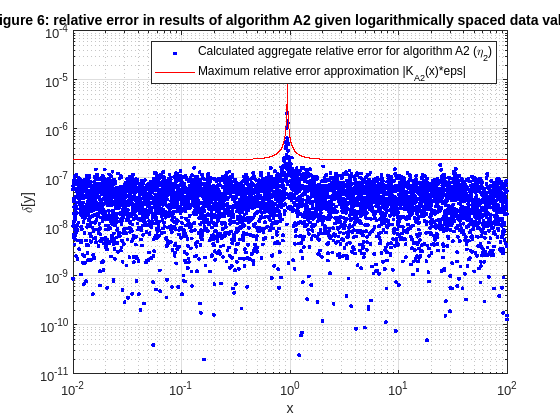


% Code for the generation of figure 6.
figure(6);
loglog(xl, dyl2, 'b.');
hold on;grid on;
loglog(xl,KA2(xl)*epssin,"r-")
xlabel('x');
ylabel('\delta[y]');
legend("Calculated aggregate relative error for algorithm A2 (\eta_{2})","Maximum relative error approximation |K_{A2}(x)*eps|")
title("Figure 6: relative error in results of algorithm A2 given logarithmically spaced data values.")
hold off;